# Bit-to-complex-symbol mapping for IQ Modulations

This functions maps a bit stream into a complex symbol stream with respect to some IQ constellations.

**Inputs:**

- *bit_TX*: bit stream vector of size *nb_bit x 1*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_bit*: number of bits in the input bit stream (= length of *bit_TX*)

**Ouputs:**

- *symb_TX*: complex symbol stream vector of size *nb_symb x 1* where *nb_symb = nb_bit / nb_bit_per_symb*

function symb_TX = mapping_QAM( bit_TX , nb_bit_per_symb , nb_bit )

if rem( nb_bit , nb_bit_per_symb ) ~= 0
    error('issue: the data stream is not an integer number of symbols')
end

nb_symb = nb_bit / nb_bit_per_symb ;                                % Number of symbols of the data stream
symb_TX = zeros( nb_symb , 1 ) ;                                    % Symbol stream vector initialization

## 4QAM constellation (<=> QPSK)

The mapping for the QPSK constellation should be done as shown below:

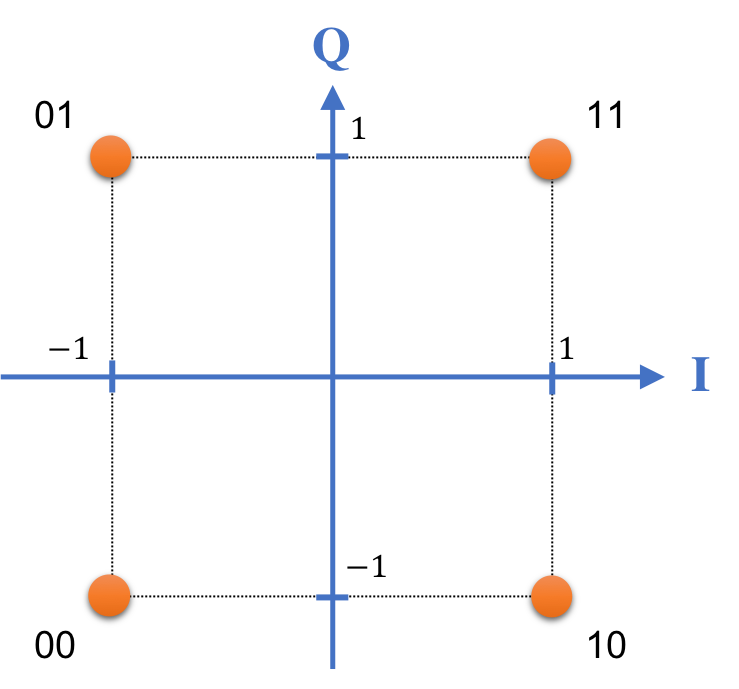

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 2
    
    % Code here the mapping function for QPSK constellation with Gray
    % coding (output: symb_TX)

end


## 16QAM constellation

The mapping for the 16QAM constellation should be done as shown below:

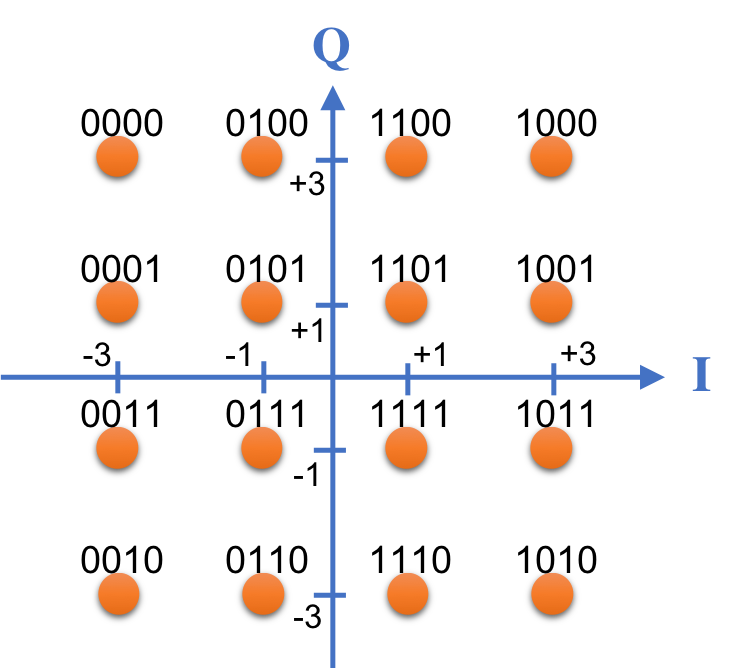

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 4
    
    % Code here the mapping function for 16QAM constellation with Gray
    % coding (output: symb_TX)

end

end